This script shows how to:

- Load LDGMs 

- Specify an effect-size distribution and simulate summary statistics based on it

- Run BLUPxldgm on the summary statistics 

- Benchmark BLUPxldgm performance across populations

clear;clc
addpath(genpath('../../MATLAB'))% add MATLAB directory and its subdirectories to path
populations = {'EUR','AFR'};
ldgms_dir = '~/Documents/data/LDGMs/1kg_chr1';

`loadLDGMs` reads LDGM precision matrices from the specified directory, together with corresponding SNP lists. If multiple populations are specified, the first output argument will have size number-of-blocks by number-of-populations.

[P, snplists] = loadLDGMs(ldgms_dir,populations);
[noBlocks, noPopns] = size(P);
head(snplists{1},3)

ans = 3×9 table
    index    anc_alleles    deriv_alleles     EUR       EAS       AMR       SAS       AFR         site_ids   
    _____    ___________    _____________    ______    ______    ______    ______    ______    ______________

      0         {'A'}           {'G'}        0.5278    0.4772    0.5476    0.4192    0.7163    {'rs6577245' }
      1         {'T'}           {'C'}        0.0775    0.0069     0.062    0.1452    0.0212    {'rs35798134'}
      2         {'G'}           {'C'}             0         0    0.0043         0    0.0552    {'rs1907567' }


Extract allele frequencies for the SNP lists for the desired populations.

AF = cell(noBlocks,noPopns);
for ii = 1:noBlocks
    % call unique() on the SNP list indices with two output arguments in
    % order to pick a representative SNP for each index
    [~,representatives] = unique(snplists{ii}.index,'stable');

    % snplists table can be sliced using the names of each column as a cell
    % array of strings
    AF(ii,:) = mat2cell(table2array(snplists{ii}(representatives,populations)),...
        length(representatives),ones(1,noPopns));
end
whos AF

  Name       Size               Bytes  Class    Attributes

  AF        79x2             14437312  cell               



### Simulations with an infinitesimal architecture

To perform simulations with an infinitesimal architecture, you just 

Total heritability, as a matrix of size equal to the number of populations, with a cross-population genetic correlation of 0.9

crosspop_heritability = 0.1 * [1 0.9; 0.9 1];

Sample size, as a vector of size equal to the number of populations

sampleSize = 1e5 * ones(1,noPopns);

use `simulateSumstats` to simulate summary statistics from an infinitesimal (Gaussian) prior distribution with the specified heritability

[sumstats, whichIndices, prior_variance, beta_perallele] = ...
    simulateSumstats(sampleSize, AF,...
    'precisionMatrices',P,...
    'heritability',crosspop_heritability);

`sumstats_inf` is a cell array of merged summary statistics tables

head(sumstats{1},3)

ans = 3×3 table
    Z_deriv_allele      AF        N  
    ______________    ______    _____

       -0.75058       0.5278    1e+05
         -0.371       0.0775    1e+05
         0.6276       0.2833    1e+05


`prior_variance` is the covariance matrix of the per-allele effect sizes

disp(prior_variance)

   1.0e-05 *

    0.1014    0.0808
    0.0808    0.0795



Run BLUPx-ldgm to get PRS weights (in per-allele units) for (1) EUR training data only and (2) AFR training data only

betaBLUPx_EUR = BLUPxldgm(P(:,1), whichIndices(:,1), sumstats(:,1), prior_variance(1), sampleSize(1));
betaBLUPx_AFR = BLUPxldgm(P(:,2), whichIndices(:,2), sumstats(:,2), prior_variance(2), sampleSize(2));

PRS weights trained with both populations

betaBLUPx_BOTH = BLUPxldgm(P, whichIndices, sumstats, prior_variance, sampleSize);

Use `r2PGS` to calculate prediction accuracy with one or both populations

r2_train_EUR = r2PGS(beta_perallele,betaBLUPx_EUR,P,whichIndices,AF);
r2_train_AFR = r2PGS(beta_perallele,betaBLUPx_AFR,P,whichIndices,AF);
r2_train_BOTH = r2PGS(beta_perallele,betaBLUPx_BOTH,P,whichIndices,AF);

Plotting

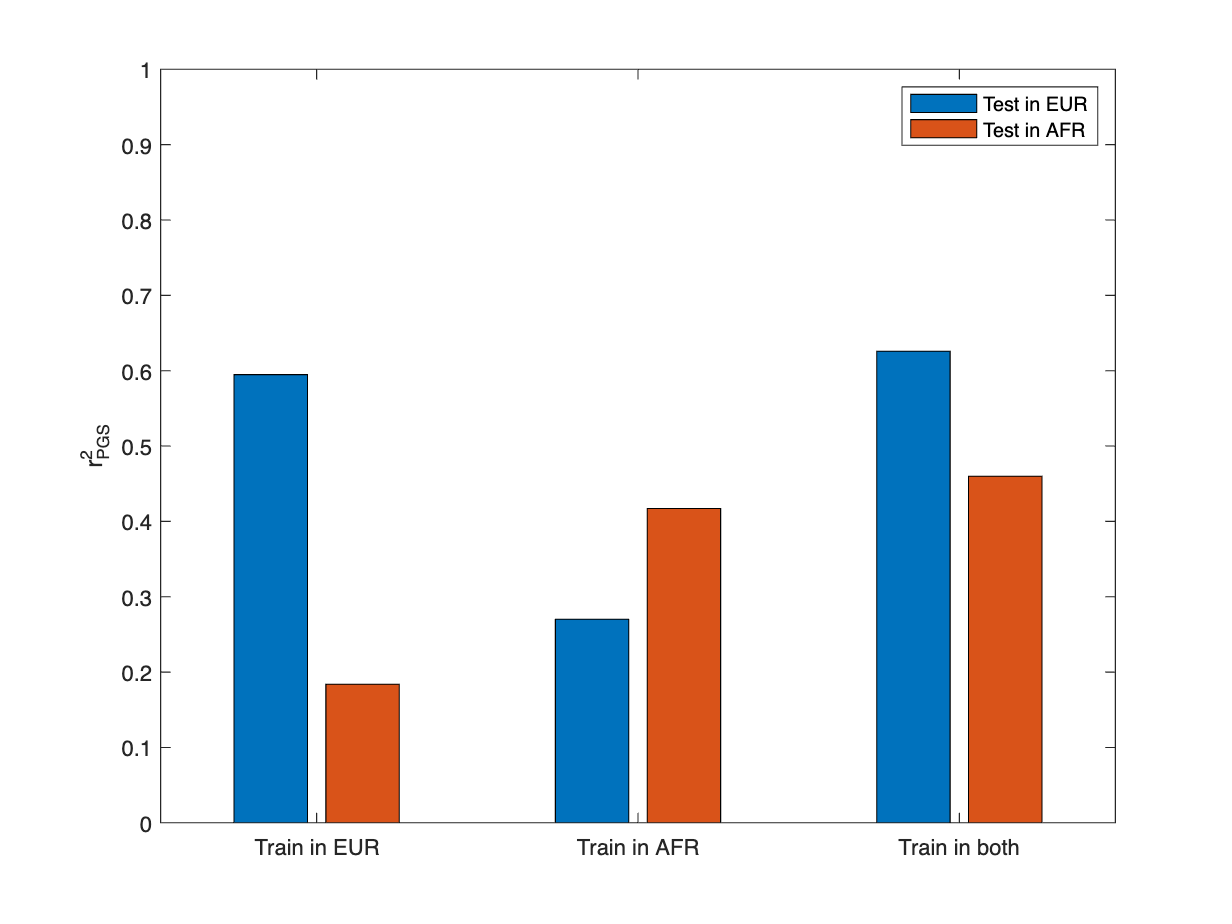

bar([r2_train_EUR;r2_train_AFR;r2_train_BOTH])
set(gca,'xtick',1:3,'xticklabel',...
    {'Train in EUR','Train in AFR','Train in both'})
ylabel('r^2_{PGS}')
ylim([0 1])
legend('Test in EUR','Test in AFR')